# Figure 1 (Methods) - Excitation lights and filters

We plot the estimated excitation light levels including the short pass filter in front of the light at 450nm in the rig. This was always present when we made the fluorescence measurements. These files are labeled ('Calib' or 'calib').

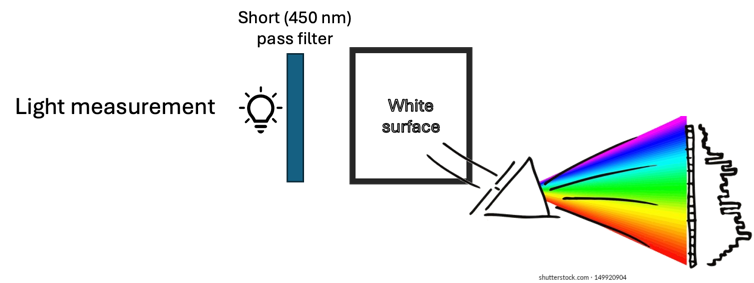

## Initialize ISET

ieInit;
waves = 380:4:700;
symbols = {'kx-','k*-','k^-','ko-'};
T = oeDatabaseLightsCreate;

## Light below 500 nm

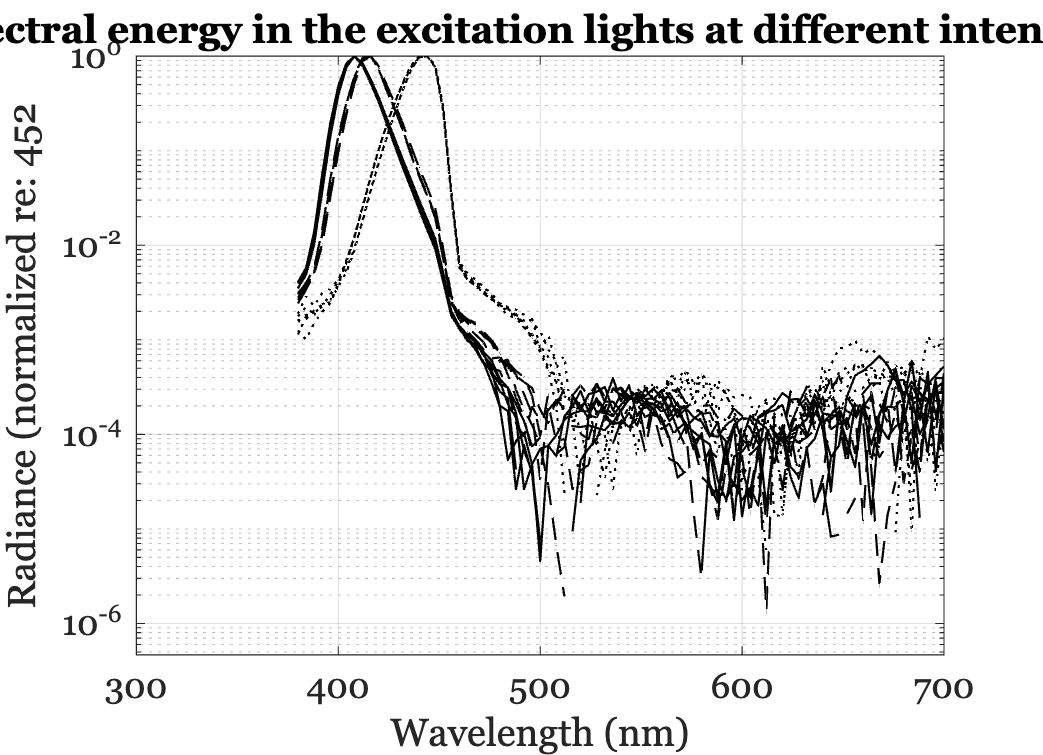

files405 = ieTableGet(T,'condition','experiment','ewave',405);
data405 = oeReadFiles(files405,'waves',waves,'normalized wave', 0);

files415 = ieTableGet(T,'condition','experiment','ewave',415);
data415 = oeReadFiles(files415,'waves',waves,'normalized wave', 0);

files450 = ieTableGet(T,'condition','experiment','ewave',450);
data450 = oeReadFiles(files450,'waves',waves,'normalized wave', 0);

ieFigure;

for ii=1:size(data405,2)
    hA = semilogy(waves,data405(:,ii),'k-'); hold on;
end
for ii=1:size(data415,2)
    hB = semilogy(waves,data415(:,ii),'k--');
end

for ii=1:size(data450,2)
    hC = semilogy(waves,data450(:,ii),'k:');
end

hold off
grid on; xlabel('Wavelength (nm)'); ylabel('Radiance (normalized re: 452');
title('Spectral energy in the excitation lights at different intensities');

## Brightest LED measures

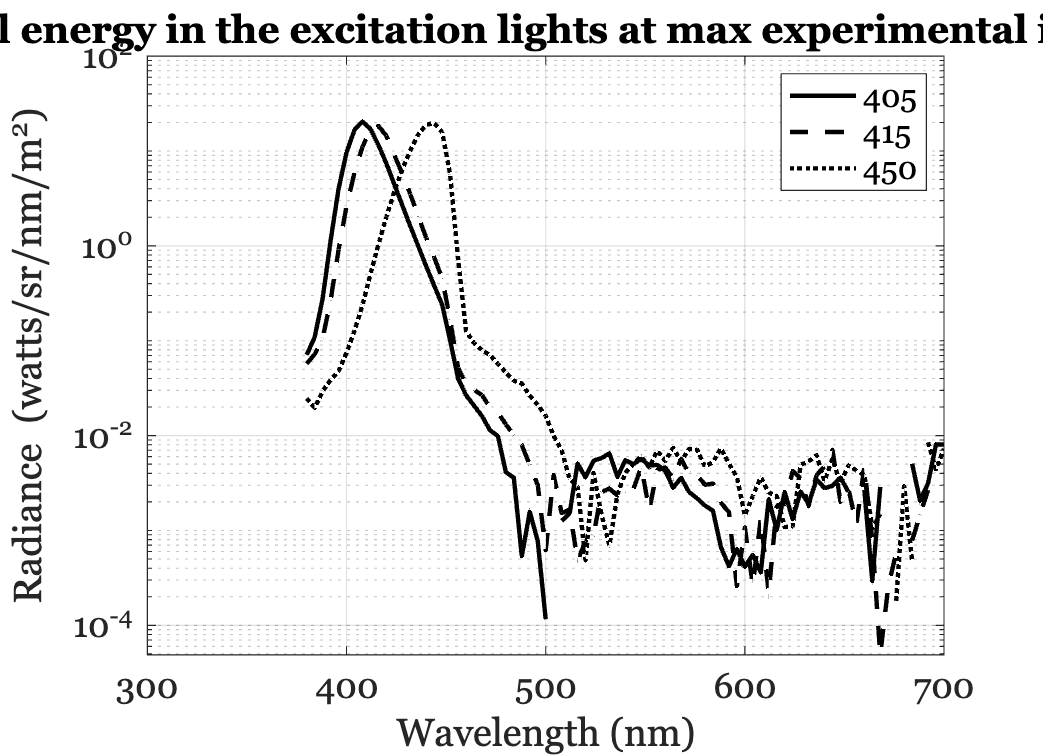

files405 = ieTableGet(T,'condition','experiment','ewave',405,'elevel',980);
data405 = oeReadFiles(files405,'waves',waves);

files415 = ieTableGet(T,'condition','experiment','ewave',415,'elevel',920);
data415 = oeReadFiles(files415,'waves',waves);

files450 = ieTableGet(T,'condition','experiment','ewave',450,'elevel',870);
data450 = oeReadFiles(files450,'waves',waves);

ieFigure;

for ii=1:size(data405,2)
    hA = semilogy(waves,data405(:,ii),'k-'); hold on;
    set(hA,'LineWidth',2);
end
for ii=1:size(data415,2)
    hB = semilogy(waves,data415(:,ii),'k--');
    set(hB,'LineWidth',2);
end

for ii=1:size(data450,2)
    hC = semilogy(waves,data450(:,ii),'k:');
    set(hC,'LineWidth',2);
end

hold off

grid on; xlabel('Wavelength (nm)'); ylabel('Radiance (watts/sr/nm/m^2)');
legend([hA,hB,hC],{'405','415','450'});
title('Spectral energy in the excitation lights at max experimental intensities');

## Estimation of unwanted reflectance

When we made the fluorescence measurements (see oeFigure1_compareSubjects) we placed a 475nm long pass filter in front of the spectroradiometer.  Its purpose is to block the reflected light from the intense short wavelength light sources.  These were at 405, 415, and 450nm.

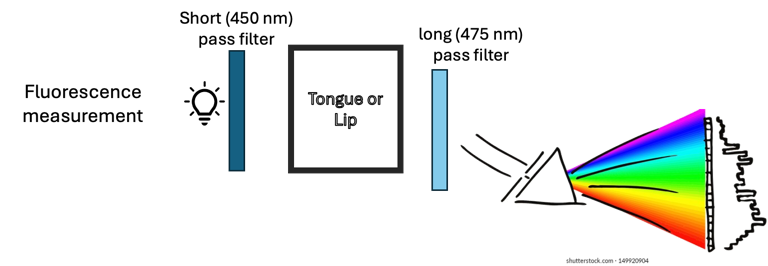

To estimate how much light might have been reflected from the tongue and still pass through the 475nm, we  made measurements (labeled 'noisecheck') replacing the tongue/lip with a white surface.  This surface had no fluorescence, so that any light that made it through would be standard reflectance.  We estimated the maximum reflected light by taking this calibration measurement and multiplying by the standard tongue reflectance.

## Using the long pass 475nm to measure the 500-700 range

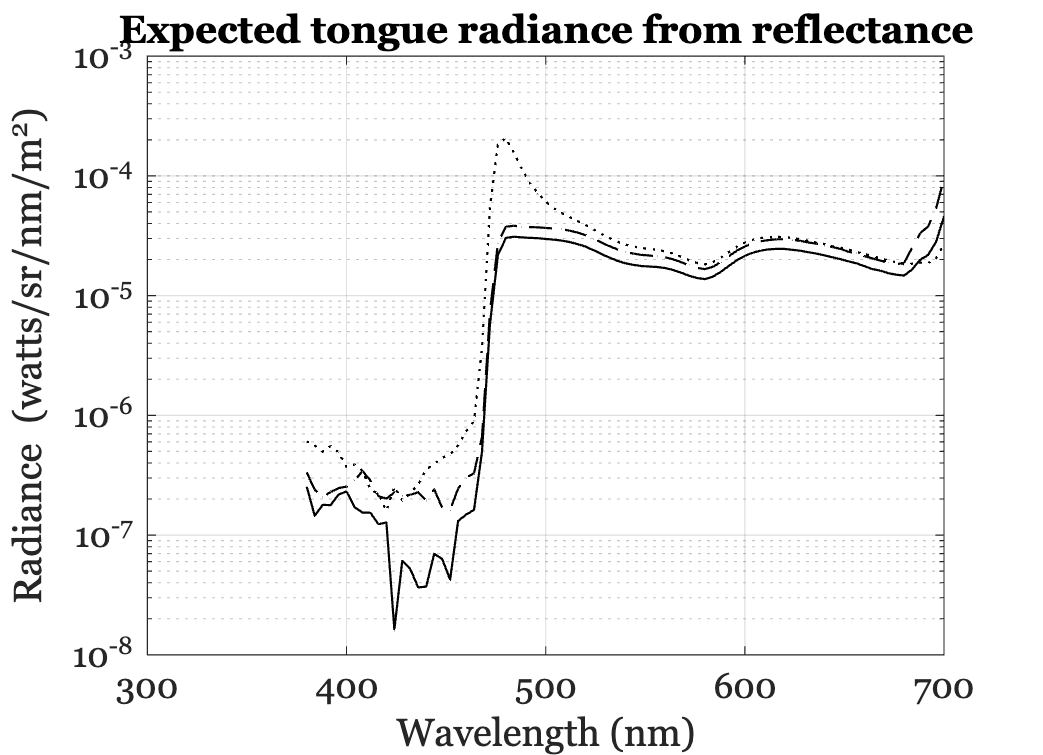

unwanted405 = ieTableGet(T,'condition','unwantedreflected','ewave',405,'elevel',980);
unwanted415 = ieTableGet(T,'condition','unwantedreflected','ewave',415,'elevel',910);
unwanted450 = ieTableGet(T,'condition','unwantedreflected','ewave',450,'elevel',870);
data405 = oeReadFiles(unwanted405,'waves',waves);
data415 = oeReadFiles(unwanted415,'waves',waves);
data450 = oeReadFiles(unwanted450,'waves',waves);

tongue = ieReadSpectra('tongue.mat',waves); 
meanTongueReflectance = mean(tongue,2);

ieFigure;
% semilogy(waves,data405,'k-',waves,data415,'k--',waves,data450,'k:'); hold on;
grid on; xlabel('Wavelength (nm)'); ylabel('Radiance (watts/sr/nm/m^2)');
semilogy(waves,data405.*meanTongueReflectance,'k-',...
    waves,data415.*meanTongueReflectance,'k--',...
    waves,data450.*meanTongueReflectance,'k:');
grid on; xlabel('Wavelength (nm)'); ylabel('Radiance (watts/sr/nm/m^2)'); 
title('Expected tongue radiance from reflectance');